# 4.2 Prony approximation

Alexandre Rey, MSE, MA-StatDig, 03.2022

clear;

addpath('../functions/');

## Example 4.3.2

Test Prony approximation with the signal $x(n)$ defined below with the same example as in the Padé.

N = 41;
n = 0:N-1;
xn = [1, 3*(0.5).^n(2:end)];
xn = xn(:); % make xn vertical
dn = [1, zeros(1,N-1)]; % unit sample

### a) Test with AR(2)

p = 2;
q = 0;

Compute the Xq matrix using the matlab `convmtx` function and chose the right index to extract the Xq as in theory eq (4.50).

X = convmtx(xn, p+1);
Xq = X(q+2:end, 2:p+1);
xq_1 = X(q+2:end, 1);
ap_ar = Xq\-xq_1

ap_ar =    -1.0714
    0.4286


ap_ar = [1; ap_ar]

ap_ar =     1.0000
   -1.0714
    0.4286


Rx = Xq'*Xq

Rx =     4.0000    3.0000
    3.0000    4.0000


rx = Xq'*xq_1

rx =     3.0000
    1.5000


The $b_q$ coefficients could be found as:

X0 = X(1:q+1, 1:p+1)

X0 =      1     0     0


bq_ar = X0*ap_ar

bq_ar = 1

en = conv(xn, ap_ar, 'same');
epq = sum(en.^2)

epq = 0.4286

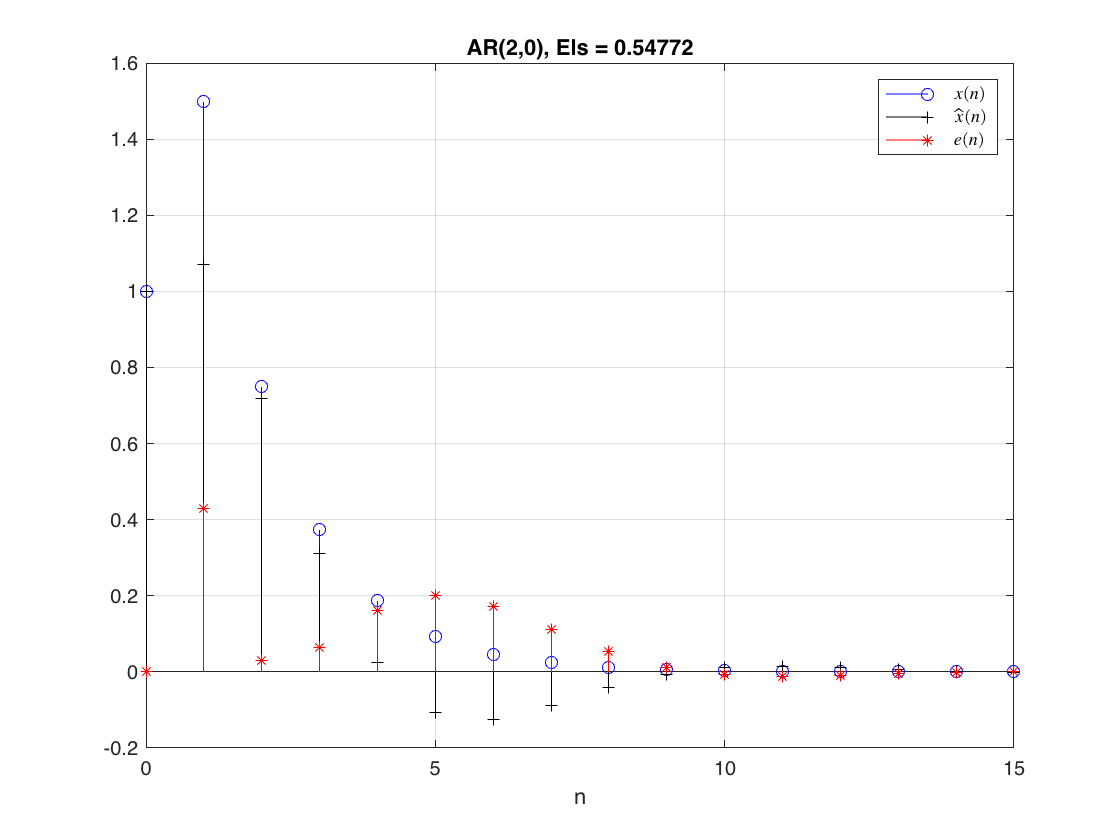

xhat_ar = impz(bq_ar, ap_ar, length(xn));
e_ar = xn-xhat_ar;
Els = sqrt(sum(e_ar.^2));
n_max=15;
figure;
    stem(n(1:n_max+1), xn(1:n_max+1), 'bo');
    hold on;
    stem(n(1:n_max+1), xhat_ar(1:n_max+1), 'k+');
    stem(n(1:n_max+1), e_ar(1:n_max+1), 'r*');
    hold off;
    title(['AR(' num2str(p) ',' num2str(q) '), Els = ' num2str(Els)]);
    legend('$x(n)$', '$\hat{x}(n)$', '$e(n)$', ...
           'Interpreter', 'latex');
    grid;
    xlabel('n');

Test of the Prony function

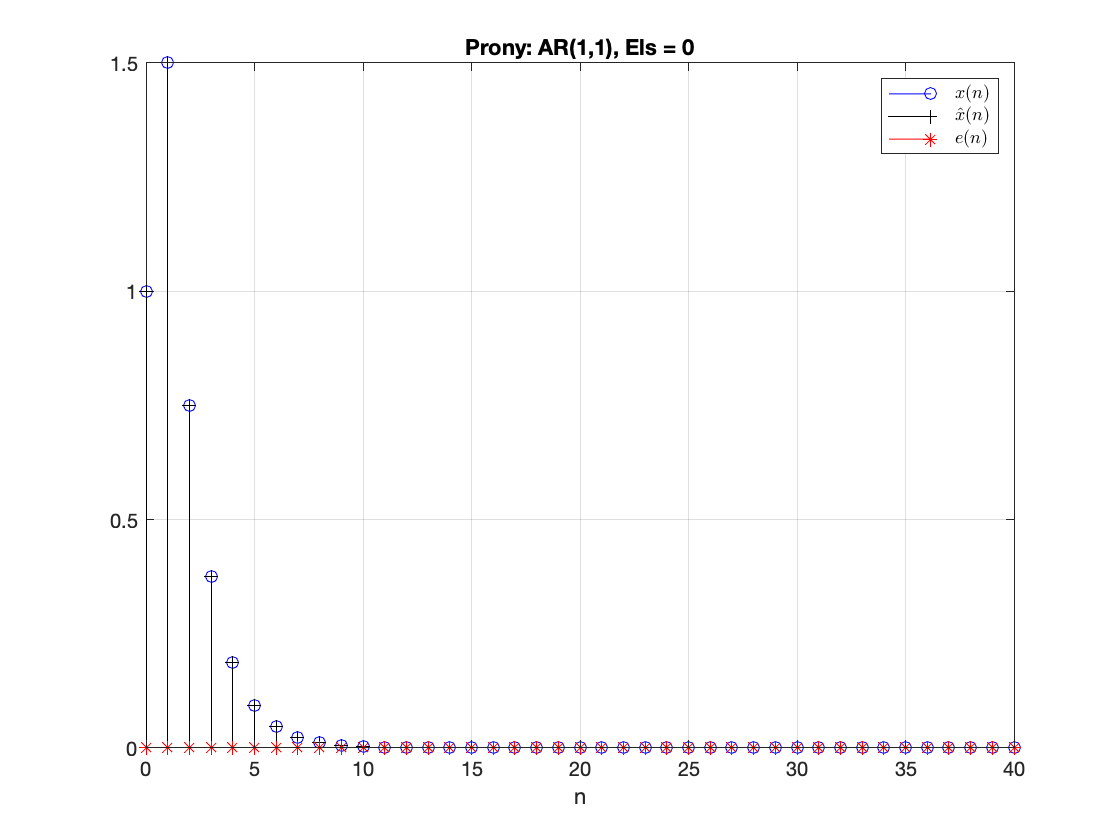

p = 1;
q = 1;
[ap_test, bq_test, xhat_test, Els_test] = myProny(xn,p,q);
e_test = xn-xhat_test;
n_max=40;
figure;
    stem(n(1:n_max+1), xn(1:n_max+1), 'bo');
    hold on;
    stem(n(1:n_max+1), xhat_test(1:n_max+1), 'k+');
    stem(n(1:n_max+1), e_test(1:n_max+1), 'r*');
    hold off;
    title(['Prony: AR(' num2str(p) ',' num2str(q) '), Els = ' num2str(Els_test)]);
    legend('$x(n)$', '$\hat{x}(n)$', '$e(n)$', ...
           'Interpreter', 'latex');
    grid;
    xlabel('n');

## Example 4.4.2: Filter design with Prony approximation of the impulse response h(n)

The proble of the filter approximation is to find the impulse response $h(n)$ of the filter from a frequency constraints.

For this exemple, to be as simple as possible we want to synthetize a filter with a frequency response $|H(jf)|=1$ for $f < F_p$ and $0$ for $F_p < f < 0.5$, aditionally we want a linear phase response then $H(jf)=e^{jn_d2\pi f}$ for $f < F_p$ and $0$ for $F_p < f < 0.5$ , the constant $n_d$ is the time delay of the filter to assure the causality of the filter.


$$H(jf) = \begin{cases}
e^{jn_d2\pi f} & |f| < 0.25\\
0 & \text{otherwise}
\end{cases}$$


Since the frequency response is a rectangular function the inverse transform is a sinc function of the variable $n$, the the impulse response is:


$$h(n) = \frac{\sin((n-n_d)\pi/2)}{(n-n_d)\pi}$$


With the function `sinc` we write it as: `hn = 1/2 * sinc((n-nd)*2*Fp)`

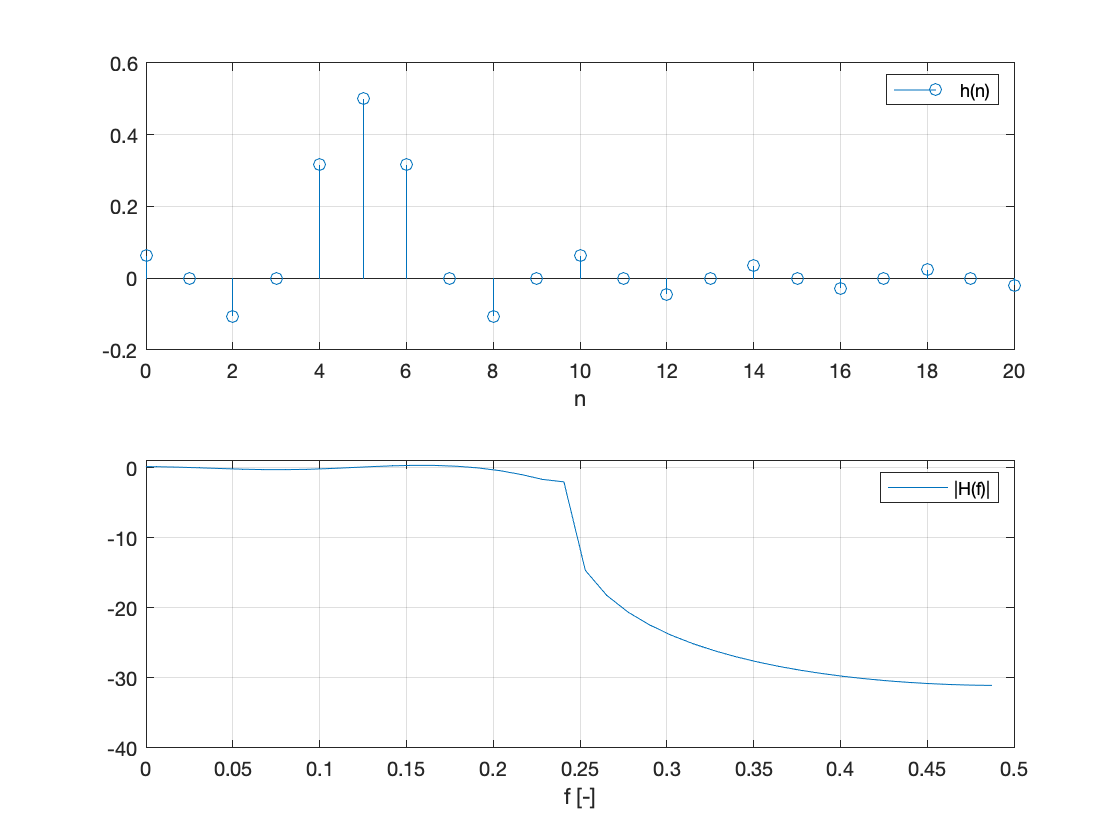

Fp = 0.25;
N = 81;
n = 0:N-1;
nd = 5;

hn = 1/2 * sinc((n-nd)*2*Fp);
H = fftshift(fft(hn));
f = -0.5:1/N:0.5-0.5/N;
figure;
    subplot(2,1,1);
         stem(n,hn);
         axis([0,20,-0.2,0.6]);
         grid;
         xlabel('n');
         legend('h(n)');
    subplot(2,1,2);
         plot(f,20*log10(abs(H)));
         axis([0,0.5,-40,1]);
         grid;
         xlabel('f [-]');
         legend('|H(f)|');

## FIR design (MA) with Prony appoximation		

If we design a FIR filter with $q=10$ and $p=0$ (MA) the Prony approximation wil give the 11 first values of the $h(n)$. In this case $b_q(n) = h(n)$ for $n = 0 \dots 10$.

p = 0;
q = 10;
[apFIR, bqFIR, xhatFIR, ElsFIR] = myProny(hn,p,q);
apFIR

apFIR = 1

bqFIR;
tfFIR = tf(bqFIR', [apFIR, zeros(1,q)], 1)

tfFIR =
 
                                                                                                                
  0.06366 z^10 - 1.949e-17 z^9 - 0.1061 z^8 + 1.949e-17 z^7 + 0.3183 z^6 + 0.5 z^5 + 0.3183 z^4 + 1.949e-17 z^3 
                                                                                                                
                                                                          - 0.1061 z^2 - 1.949e-17 z + 0.06366  
                                                                                                                
  --------------------------------------------------------------------------------------------------------------
                                                           
                                                       z^10
                                                           
 
Sample time: 1 seconds
Discrete-time transfer function.



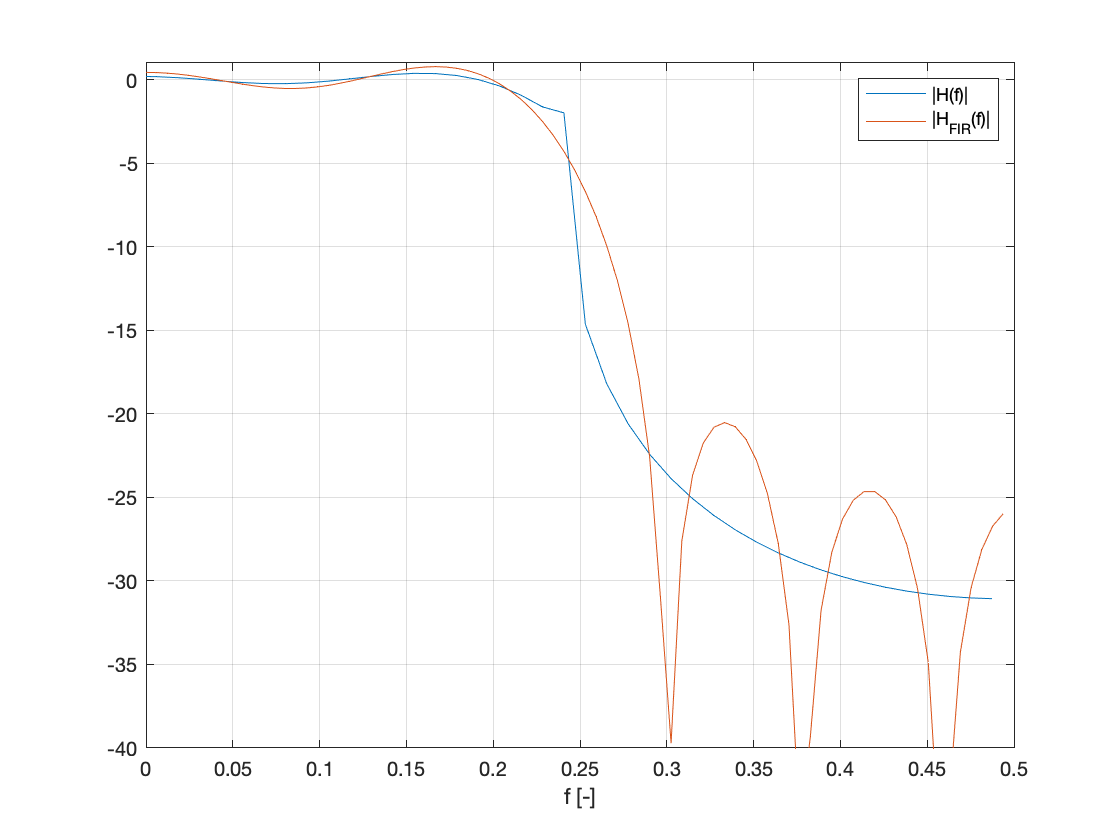

[H_FIR, f_FIR] = freqz(bqFIR, apFIR, N, 1);

figure;
    plot(f,20*log10(abs(H)), ...
         f_FIR, 20*log10(abs(H_FIR)));
    axis([0,0.5,-40,1]);
    grid;
    xlabel('f [-]');
    legend('|H(f)|', '|H_{FIR}(f)|');

### Pade approximation

We want to find the transfer fuction of an ARMA system with $p=5$ and $q=5$. First test with Padé

p = 5;
q = 5;
[ap_pa, bq_pa, ~, Els_pa] = myPade(hn(1:p+q+1), p, q)

ap_pa =     1.0000
   -2.5256
    3.6774
   -3.4853
    2.1307
   -0.7034


bq_pa =     0.0637
   -0.1608
    0.1280
    0.0461
    0.0638
    0.0211


Els_pa = 1.8108e-15

Hpa = tf(bq_pa', ap_pa', 1)

Hpa =
 
  0.06366 z^5 - 0.1608 z^4 + 0.128 z^3 + 0.04609 z^2 + 0.06377 z + 0.02111
  ------------------------------------------------------------------------
         z^5 - 2.526 z^4 + 3.677 z^3 - 3.485 z^2 + 2.131 z - 0.7034
 
Sample time: 1 seconds
Discrete-time transfer function.



And test the same with Prony

[ap_pr, bq_pr, ~, Els_pr] = myProny(hn, p, q)

ap_pr =     1.0000
   -1.9093
    2.3740
   -1.9531
    1.0350
   -0.2893


bq_pr =     0.0637
   -0.1216
    0.0450
    0.0783
    0.1323
    0.0810


Els_pr = 0.0790

Hpr = tf(bq_pr', ap_pr', 1)

Hpr =
 
  0.06366 z^5 - 0.1216 z^4 + 0.04503 z^3 + 0.07825 z^2 + 0.1323 z + 0.08105
  -------------------------------------------------------------------------
         z^5 - 1.909 z^4 + 2.374 z^3 - 1.953 z^2 + 1.035 z - 0.2893
 
Sample time: 1 seconds
Discrete-time transfer function.



As before we will plot the frequency response compared to the desired frequency response $H(f)$:

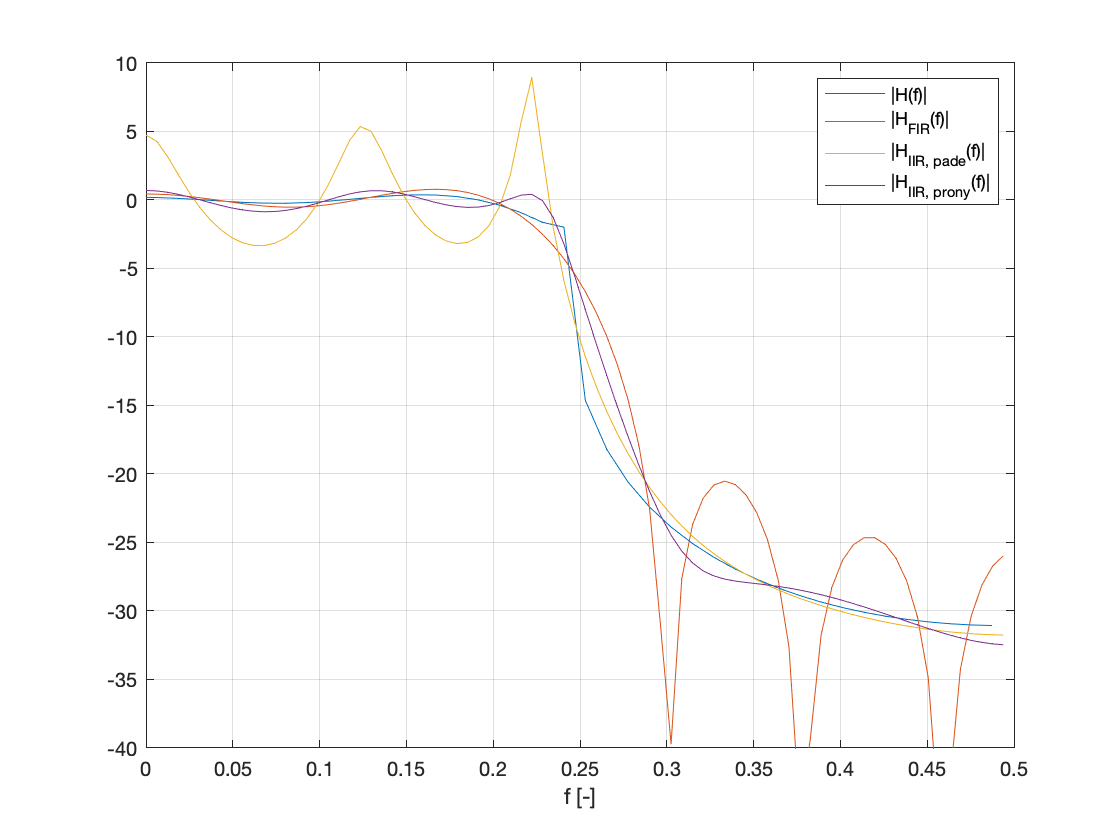

[H_pa, f_pa] = freqz(bq_pa, ap_pa, N, 1);
[H_pr, f_pr] = freqz(bq_pr, ap_pr, N, 1);

figure;
    plot(f,20*log10(abs(H)), ...
         f_FIR, 20*log10(abs(H_FIR)), ...
         f_pa, 20*log10(abs(H_pa)), ...
         f_pr, 20*log10(abs(H_pr)));
    axis([0,0.5,-40,10]);
    grid;
    xlabel('f [-]');
    legend('|H(f)|', ...
           '|H_{FIR}(f)|', ...
           '|H_{IIR, pade}(f)|', ...
           '|H_{IIR, prony}(f)|');

The impulse response of the synthetized filter is compared to the desired impulse response $h(n)$:

h_pr = impz(bq_pr, ap_pr, length(hn));
Els = norm(hn-h_pr)

Els = 6.2350

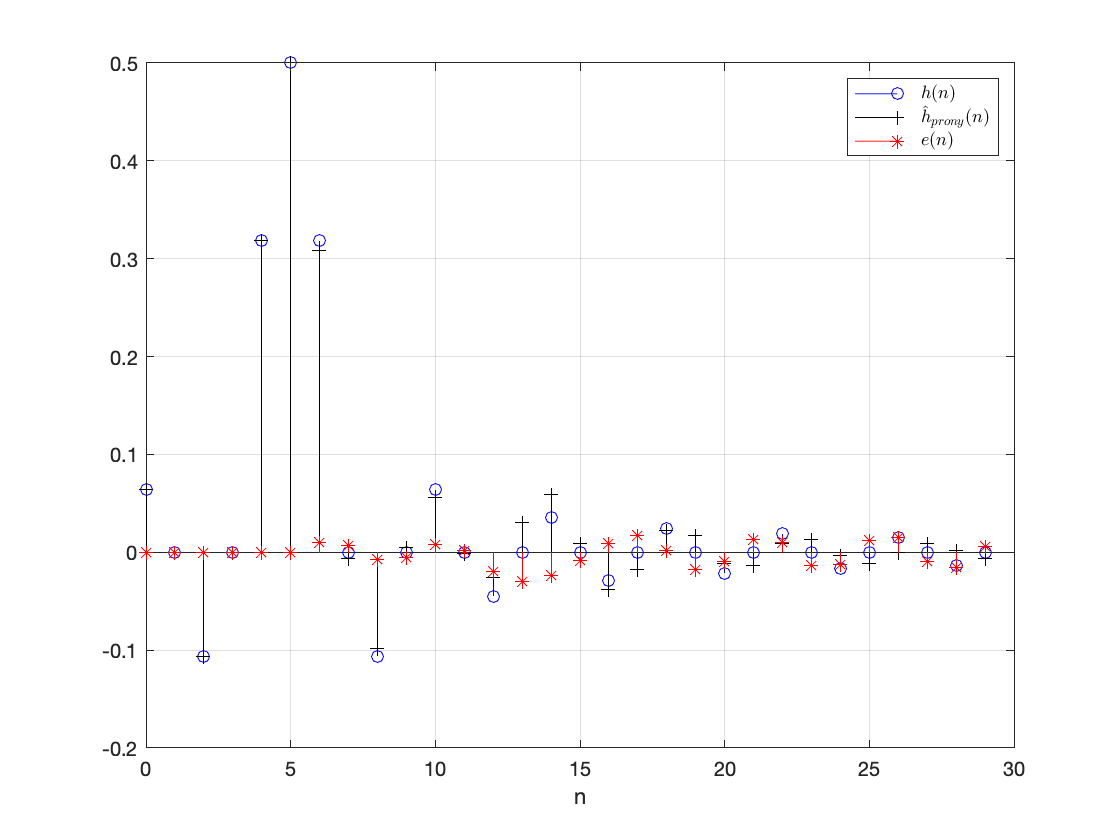

n_max = 30;
figure;
    stem(n(1:n_max), hn(1:n_max), 'ob');
    hold on;
    stem(n(1:n_max), h_pr(1:n_max)', '+k');
    stem(n(1:n_max), hn(1:n_max)-h_pr(1:n_max)', '*r');
    hold off;
    legend('$h(n)$', '$\hat{h}_{prony}(n)$', '$e(n)$', ...
           'Interpreter', 'latex');
    grid on;
    xlabel('n');

## Shanks approximation

Write the shanks function with the heading as follows:

p = 5;
q = 5;
[ap_sh, bq_sh, Els_sh] = myShanks(hn, p, q)

ap_sh =     1.0000
   -1.9093
    2.3740
   -1.9531
    1.0350
   -0.2893


bq_sh =     0.0637
   -0.1228
    0.0490
    0.0729
    0.1345
    0.0835


Els_sh = 0.0061

We observe the coefficiens are a bit different compared those obtained with the Prony method.

[bq_pr, bq_sh]

ans =     0.0637    0.0637
   -0.1216   -0.1228
    0.0450    0.0490
    0.0783    0.0729
    0.1323    0.1345
    0.0810    0.0835


h_sh = impz(bq_sh, ap_sh, length(hn))'

h_sh =     0.0637   -0.0012   -0.1044    0.0007    0.3156    0.5000    0.3147   -0.0009   -0.0986    0.0022    0.0556    0.0002   -0.0254    0.0287    0.0587    0.0101   -0.0376   -0.0182    0.0218    0.0179   -0.0112   -0.0134    0.0081    0.0133   -0.0034   -0.0115   -0.0002    0.0088    0.0023   -0.0061   -0.0029    0.0041    0.0032   -0.0026   -0.0030    0.0013    0.0027   -0.0004   -0.0021   -0.0001    0.0016    0.0005   -0.0012   -0.0006    0.0008    0.0006   -0.0005   -0.0006    0.0002    0.0005


Els = norm(hn-h_sh)

Els = 0.0784

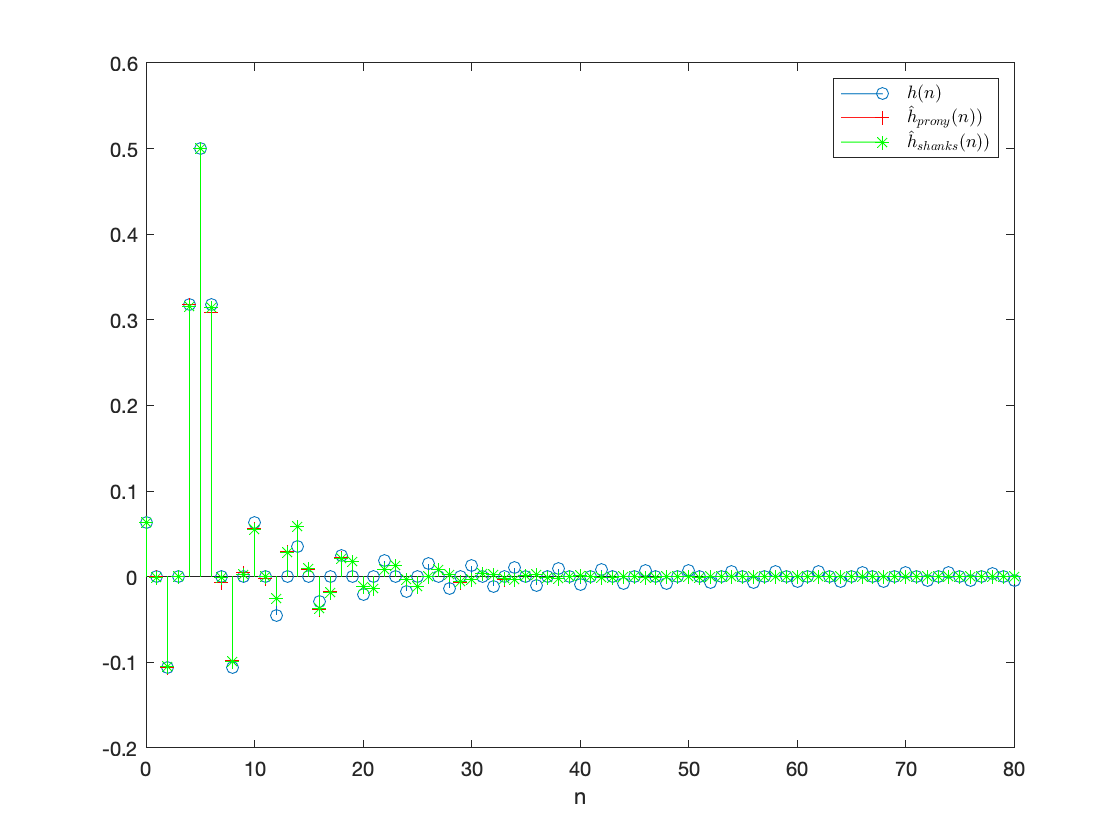

figure;
    stem(n, hn);
    hold on;
    stem(n, h_pr, '+r')
    stem(n, h_sh, '*g');
    hold off;
    legend('$h(n)$', ...
           '$\hat{h}_{prony}(n)$)', ...
           '$\hat{h}_{shanks}(n)$)', ...
           'Interpreter', 'latex');
    xlabel('n');

As before we will plot the frequency response compared to the desired frequency response $H(f)$:

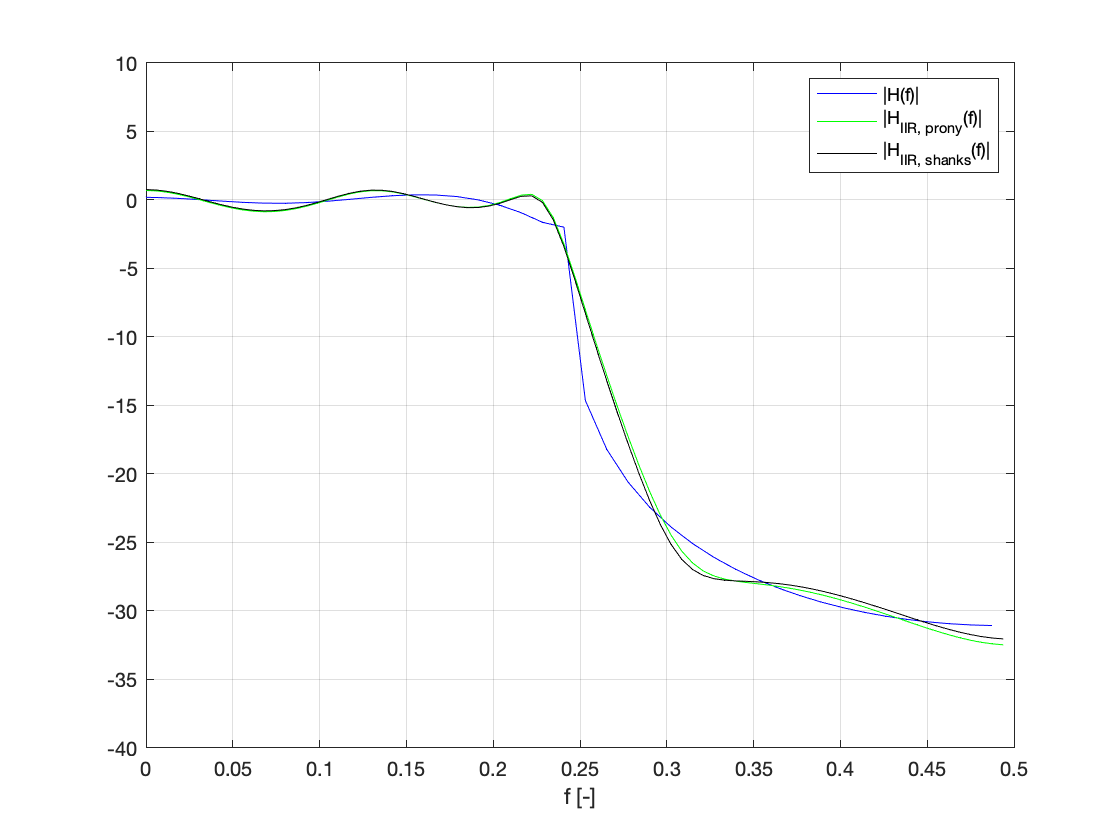

[H_sh, f_sh] = freqz(bq_sh, ap_sh, N, 1);
    
figure;
    plot(f,20*log10(abs(H)), 'b', ...
         f_pr, 20*log10(abs(H_pr)), 'g', ...
         f_sh, 20*log10(abs(H_sh)), 'k');
    axis([0,0.5,-40,10]);
    grid;
    xlabel('f [-]');
    legend('|H(f)|', '|H_{IIR, prony}(f)|', '|H_{IIR, shanks}(f)|');